Ejemplo de diseño de filtro digital

autor: Filipuzzi, Fernando Rafael

versión: 20230314

Matlab:2022b

function [N,e]=mi_cheb1ord(Wc, Ws, Ap, As)
    

**Cálculo del riple con la atenuación en la banda de paso**

              

e=sqrt(10^(Ap/10)-1);

**Cálculo del orden en la banda de rechazo (suprimida)**

            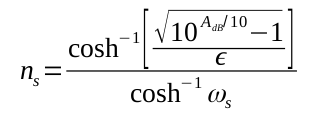

ns=acosh( sqrt(10^(As/10)-1)/e )/acosh(Ws);

**Cálculo del orden en la frecuencia de corte 3db**

        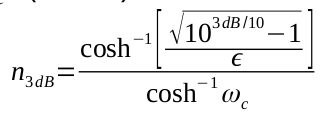

A3db=3;
n3db=acosh( sqrt(10^(A3db/10)-1)/e )/acosh(Wc);

determina el orden máximo

n=ceil(n3db);
if ns>n
    n=ceil(ns);
end

N=n;